# Simulating (pre learning noisy phase + learning phase + post learning noisy phase)

clc; clear;
N = 400; T_noise = 100; T_learning = 100;
net = IzhikevichNetwork(N, 'g_ee', 0.5, 'g_ei', 2, 'g_ie', 2); 
net.tau_A = 5;
net.sigma_ex = sqrt(0.5)*5;
net.sigma_inh = sqrt(0.5)*2;

% Noise driven activity before learning
net.noise = true;
net.run(T_noise * 1000); 
net.noise = false;

% learning window
net.STDP = true; net.stimulation = true;
stim = Stimulation(net, 100, 2, 30, 50, 5);
net.run(T_learning * 1000); 
net.STDP = false; net.stimulation = false;

% Noise driven activity post learning
net.noise = true;
net.run(T_noise * 1000); 
net.noise = false;

data = net.getData();

% Define the folder path
folder = fullfile("Results");

% Create the folder if it doesn't exist
if ~exist(folder, 'dir')
    mkdir(folder);
end

# Raw raster

fig = figure('Units', 'normalized', 'Position', [0.1 0.1 0.5 0.5]);
sgtitle("Effect of Learning on Noise-Driven Spiking Activity in the Network", 'fontName', "Times New Roman",  'Interpreter', 'latex')
ms = 3;

subplot(1,2,1); hold on; axis square;
t_min = 0; t_max = T_noise;
idx = (data.firings(1, :) > t_min * 1000) & (data.firings(1, :) < t_max * 1000);
firings = data.firings(:, idx);
firings(1, :) = firings(1, :) - t_min * 1000;
firings_pre = firings;

ex_idx = firings(2, :) <= net.Ne;
scatter(firings(1, ex_idx)/1000, firings(2, ex_idx), ms, 'blue', 'filled');
scatter(firings(1, ~ex_idx)/1000, firings(2, ~ex_idx), ms, 'r', 'filled');
xlabel("time, s", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel("cell index", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
title("Pre-Learning", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'FontName', 'Times New Roman');

subplot(1,2,2); hold on; axis square;
t_min = T_learning + T_noise; t_max = T_learning + 2*T_noise;
idx = (data.firings(1, :) > t_min * 1000) & (data.firings(1, :) < t_max * 1000);
firings = data.firings(:, idx);
firings(1, :) = firings(1, :) - t_min * 1000;
firings_post = firings;

ex_idx = firings(2, :) <= net.Ne;
scatter(firings(1, ex_idx)/1000, firings(2, ex_idx), ms, 'blue', 'filled');
scatter(firings(1, ~ex_idx)/1000, firings(2, ~ex_idx), ms, 'r', 'filled');
xlabel("time, s", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel("cell index", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
title("Post-Learning", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'FontName', 'Times New Roman');
% exportgraphics(fig, "Results\\BeforeAfterSpontaneousActivity.pdf", ContentType="vector");

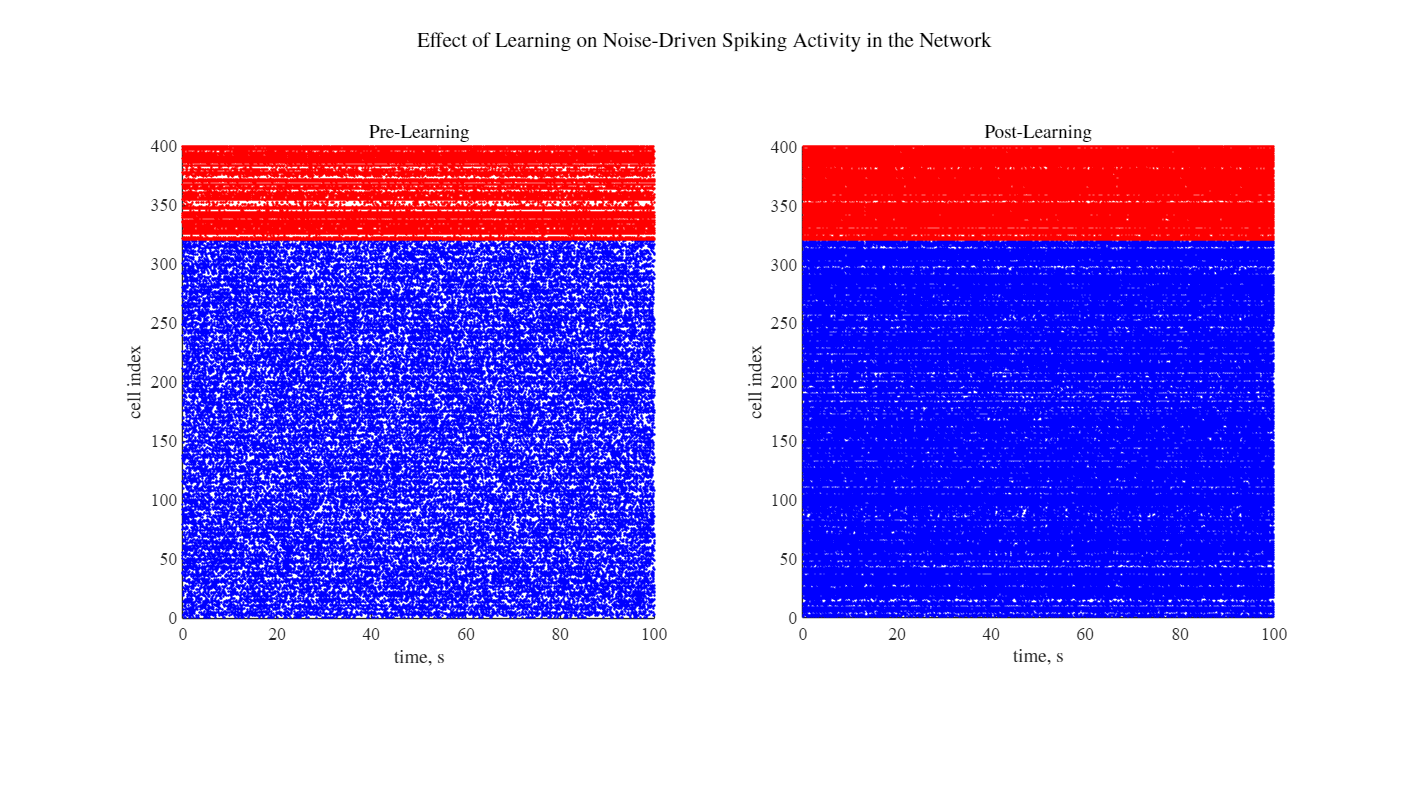

% exportgraphics(fig, "Results\\BeforeAfterSpontaneousActivity.png", ContentType="image");

% Example: rasters is N x T (neurons x time)
 
raster_pre = utils.getRasterPlot(firings_pre, 0.1);
raster_post = utils.getRasterPlot(firings_post, 0.1);

% figure(Position=[0.5, 0.5, 3000, 600]); imagesc(raster);
% set(gca, 'ydir', 'normal');


% Apply DFT on each row (neuron): get power spectrum per neuron
fft_result_pre = fft(raster_pre, [], 2);  % size: [50 x 1000]
fft_result_post = fft(raster_post, [], 2);  % size: [50 x 1000]

% Optionally: get power spectrum
power_spectrum_pre = abs(fft_result_pre).^2;
power_spectrum_post = abs(fft_result_post).^2;

% Mean power across neurons
mean_power_pre = mean(power_spectrum_pre, 1);
mean_power_post = mean(power_spectrum_post, 1);

% Frequency axis
Fs = 10000;  % sampling frequency in Hz
N = size(raster, 2);
f = Fs * (0:N-1) / N;

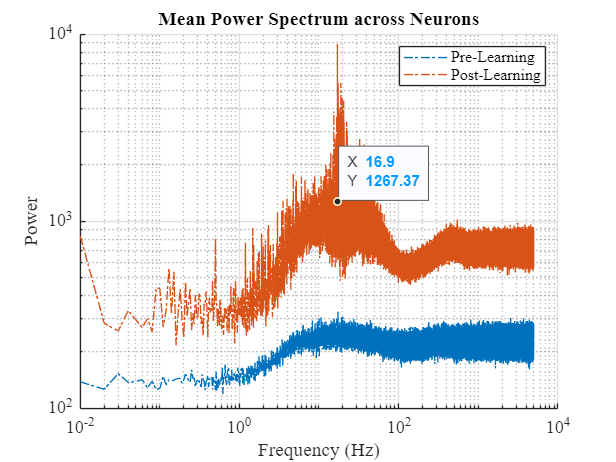

figure(); hold on;

% Plot both conditions
loglog(f(1:N/2), mean_power_pre(1:N/2), '-.', 'MarkerSize', 5);
loglog(f(1:N/2), mean_power_post(1:N/2), '-.', 'MarkerSize', 5);

% Axis labels and title


xlabel('Frequency (Hz)');
ylabel('Power');
title('Mean Power Spectrum across Neurons');

% Optional: set log scale manually (redundant with loglog, but safe)
set(gca, 'XScale', 'log', 'YScale', 'log');

% xlim([10, 100])
% Optional: legend and grid
legend('Pre-Learning', 'Post-Learning');
grid on;

idx = f > 17 & f < 100;  % range to fit
log_f = log10(f(idx));
log_P = log10(mean_power_post(idx));
coeff = polyfit(log_f, log_P, 1);
alpha = -coeff(1)

alpha = 0.4243

figure();
imagesc(f(1:N/2), 1:400, log10(power_spectrum_pre(:,1:N/2)));
xlabel('Frequency (Hz)'); ylabel('Neuron'); colorbar;

# Filtered Rasters

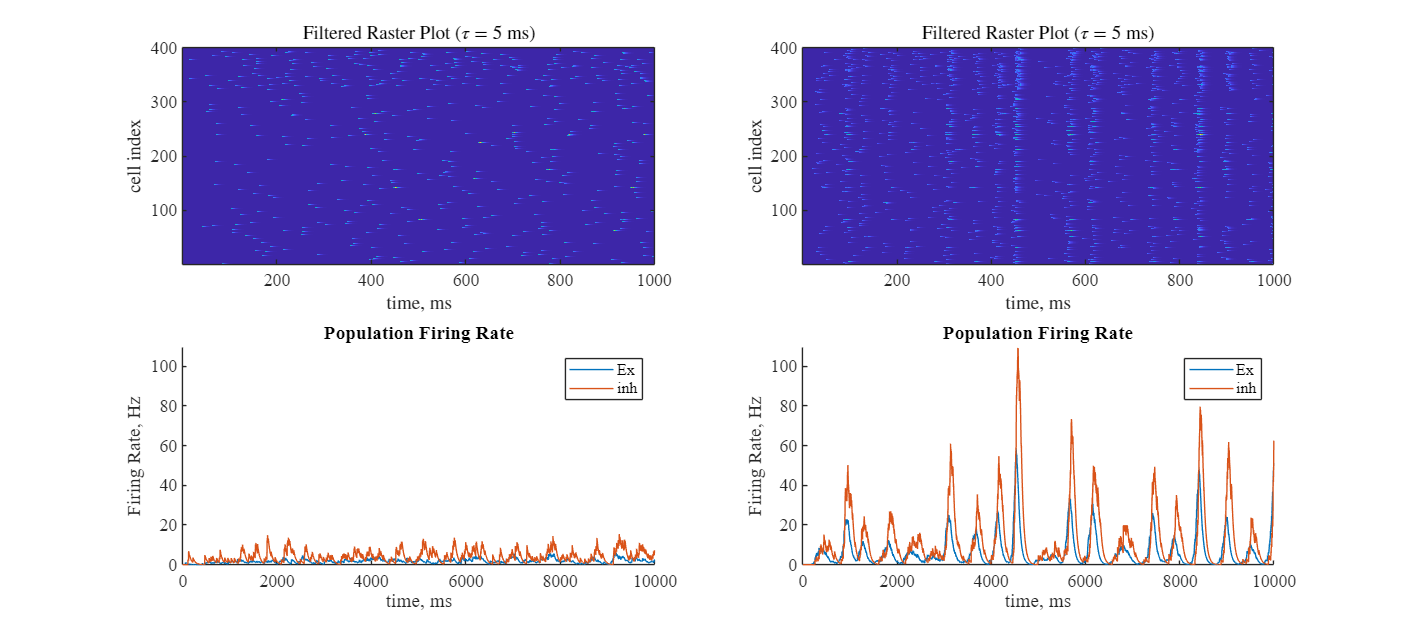

fig = figure('Units', 'normalized', 'Position', [0.1 0.1 0.5 0.4]);
tau = 5; 

subplot(2, 2, 1);
filtered_raster = utils.LowPassFilter(firings_pre, 1000*(t_max-t_min), tau);
imagesc(filtered_raster); 
% cb = colorbar('Location', 'northoutside'); cb.Label.String = "Firing Rate, Hz";
xticks((0:0.2:t_max-t_min)*10000); xticklabels(1000*(0:0.2:t_max-t_min));
xlabel("time, ms", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel("cell index", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
title(sprintf("Filtered Raster Plot ($\\tau = %d$ ms)", tau), 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'ydir', 'normal', 'FontName', 'Times New Roman');

ax3 = subplot(2, 2, 3);
fr_ex = 1000*mean(filtered_raster(1:320, :), 1);
fr_inh = 1000*mean(filtered_raster(321:end, :), 1);
hold on;
plot(fr_ex, DisplayName="Ex")
plot(fr_inh, DisplayName="inh")
legend();
xlabel("time, ms"); ylabel("Firing Rate, Hz"); 
title("Population Firing Rate")

subplot(2, 2, 2); 
filtered_raster = utils.LowPassFilter(firings_post, 1000*(t_max-t_min), tau);
imagesc(filtered_raster); 
% cb = colorbar(); cb.Label.String = "Firing Rate, Hz";
xticks((0:0.2:t_max-t_min)*10000); xticklabels(1000*(0:0.2:t_max-t_min));
xlabel("time, ms", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel("cell index", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
title(sprintf("Filtered Raster Plot ($\\tau = %d$ ms)", tau), 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'ydir', 'normal', 'FontName', 'Times New Roman');

ax4 = subplot(2, 2, 4);
fr_ex = 1000*mean(filtered_raster(1:320, :), 1);
fr_inh = 1000*mean(filtered_raster(321:end, :), 1);
hold on;
plot(fr_ex, DisplayName="Ex")
plot(fr_inh, DisplayName="inh")
legend(); 
xlabel("time, ms"); ylabel("Firing Rate, Hz"); 
title("Population Firing Rate")

% Link y-axes of both plots
linkaxes([ax3, ax4], 'y');
exportgraphics(fig, "FirigRate.png", ContentType="vector");

# Binned Raster

figure('Units', 'normalized', 'Position', [0.1 0.1 0.5 0.4]);

subplot(2, 1, 1);
bin_size = 10;
binned_raster = utils.getRasterPlot(firings_pre, bin_size);
imagesc(binned_raster); 
cb = colorbar(); cb.Label.String = "Spike Count";
xlabel("time, ms", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
ylabel("cell index", 'Interpreter', 'latex', 'FontName', 'Times New Roman');
title(sprintf("Binned Raster Plot ($bin size = %d$ ms)", bin_size), 'Interpreter', 'latex', 'FontName', 'Times New Roman');
set(gca, 'ydir');

  2×1 cell array

    {'normal' }
    {'reverse'}



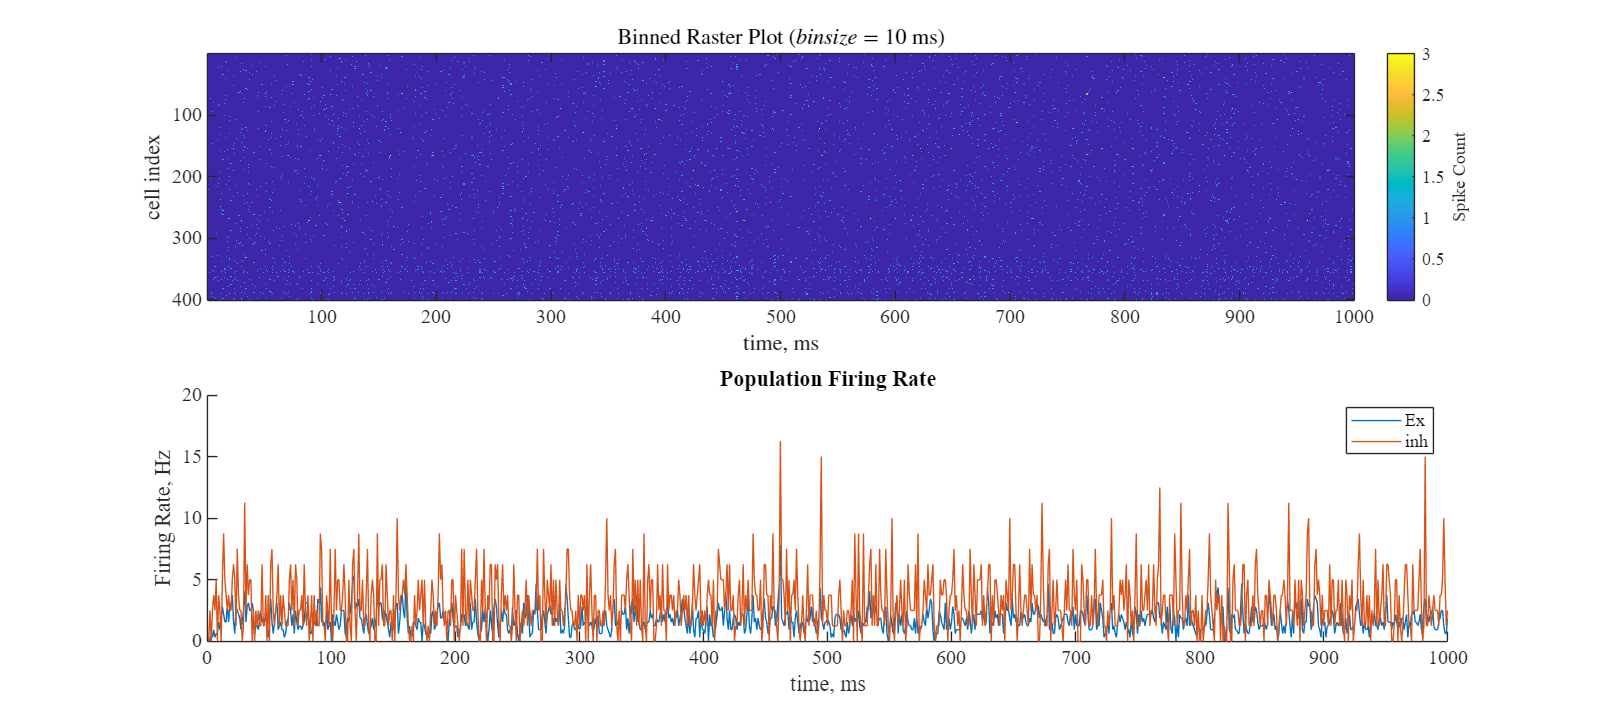


subplot(2, 1, 2);
fr_ex = mean(binned_raster(1:320, :), 1)/(bin_size*0.001);
fr_inh = mean(binned_raster(321:end, :), 1)/(bin_size*0.001);
hold on;
plot(fr_ex, DisplayName="Ex")
plot(fr_inh, DisplayName="inh")
legend(); 
xlabel("time, ms"); ylabel("Firing Rate, Hz"); 
title("Population Firing Rate")


figure; hold on;
histogram(fr_ex(:))
histogram(fr_inh(:))

figure; hold on;
histogram(fr_ex(:))
histogram(fr_inh(:))

figure;
dist = 1 - squareform(pdist(binned_raster, "correlation"));
imagesc(dist); cb = colorbar();
axis square;
